# Seguimiento N° 2

**Teoría Macroeconómica I **

**Estudiante**: Valentina Andrade de la Horra                 **Fecha**:  19 de marzo 2022

**Profesor**: Alexandre Janiak    **Ayudante:** Pablo Vega y Bianca Hincapié

En el siguiente seguimiento aprenderé como se aproxima una integral mediante una **cuadratura** numérica. 

## Descripción del seguimiento

En general, una integral de una función univariada f : $R\longrightarrow R$ sobre un intervalo $\left\lbrack a,b\right\rbrack$ se aproxima mediante la siguiente suma ponderada


$$\int_a^b f\left(z\right)\textrm{dz}\;\approx \sum_{i=0}^n w_i \cdot f\left(x_i \right)\;$$
                                              
$$\left(p\right)$$


Donde $x_i$ denotan los nodos de cuadratura y $w_i$ las ponderaciones de cada nodo. Las cuadraturas de Newton-Cotes aproximan (p) mediante la integral de un polinomio interpolante construido sobre nodos equidistantes en el intervalo $\left\lbrack a,b\right\rbrack \ldotp$

Las reglas abiertas no incluyen las cotas de los intervalos $\left\lbrack a,b\right\rbrack \;$como nodos de cuadratura y las reglas cerradas si los incluyen. 

Considere un número **impar **de nodos $x$ y las siguientes reglas para ponderaciones ${w_i }_{\;}$:


$$\textrm{Trapezoide}:w_{i\;\;} =\left\lbrace \begin{array}{ll}
\frac{h}{2} & i=\left\lbrace 1,n\right\rbrace \\
h & i\not= \left\lbrace 1,n\right\rbrace 
\end{array}\right.$$
                                           
$$\left(q_1 \right)$$



$$\textrm{Simpson}:w_{i\;} \;\;\;\;\;=\;$$

$$ \begin{cases} \frac{h}{3} & \text{i = {1,n}}
\\ \frac{2h}{3}   & \text{i impar, i} & \neq \text{{1,n}, n : impar}  \\
\frac{4h}{3}  & \text{i par, i} \neq {1,n} \end{cases}$$
    
$$\left(q_2 \right)$$


Donde $n$ denota el número de nodos y ${\;h}^2$ corresponde al largo de cada subintervalo interpolado. Note que $q_1$ y $q_2$ corresponden a reglas cerradas. 

Se pide aproximar las siguientes integrales utilizando las reglas descritas


$$\begin{array}{l}
I_1 =\int_0^1 \left(x^4 +x{\;}^3 \right)\textrm{dx}\;\;,\;\;\textrm{donde}\;f\left(x_1 \right)=x^4 +x{\;}^3 \\
I_2 =\int_0^1 \sin \;|\pi \;x|\textrm{dx},\;\;\;\;\;\textrm{donde}\;f\left(x_2 \right)=\sin \;|\pi \;x|
\end{array}$$


## (a) Aproxime las integrales $I_{1\;} \;y\;I_2$ utilizando las reglas $\left(q_1 \right)\;,\left(q_2 \right)\;\textrm{con}\;n=31\;\textrm{nodos}$.

En ambos casos podemos decir que el **step size** $h$ es 


$$h=\frac{b-a}{N}=\frac{1-0}{31}=0\ldotp 0323\;$$


Entonces tendremos tantos $f\left(x_n \right)\;\textrm{para}\;\textrm{llegar}\;\textrm{desde}\;0\;a\;1\;\textrm{con}\;\textrm{puntos}\;\textrm{con}\;\textrm{avance}\;\textrm{en}\;h\;$. Eso implica que con tendremos que hacer una sumatoria de las funciones desde el límite más bajo al más alto. Utilizando el cambio de variable (A.5) indicado en el anexo concluímos que con la **regla del trapezoide podemos: **


$$\int_a^b f\left(x\right)\textrm{dx}\approx \frac{h}{2}\;\left\lbrack f\left(a\right)+2\left\lbrace f\left(x_1 \right)+f\left(x_2 \right)+f\left(x_3 \right)+\ldotp \ldotp \ldotp +f\left(x_{N-1} \right)\right\rbrace +f\left(b\right)\right\rbrack$$


En el archivo [integracion_newton.m](matlab:open('./integracion_newton.m')) he creado una forma de hacer más simple este proceso 

f = input ('Ingresa la función: ');
N = input('Ingresa el número de nodos: ');
a = input('Ingresa el límite inferior: ');
b = input('Ingresa el límite superior: ');
h = (b-a)/N;
sum = 0; % Para hacer más eficiente el proceso

for i = 1:N-1
    sum = sum + f(a+ i*h); % Notemos que es (A.5)
end
TP = (h/2)*(f(a) + 2*sum + f(b)) ; 
fprintf('El resultado usando la regla del trapezoide es que el valor de la integral es:  %.6f\n', TP)

El resultado usando la regla del trapezoide es que el valor de la integral es:  0.450607


*Si pones en tu consola integracion_newton pedirá cada uno de los parámetros. *

%integracion_newton

Result using trapezoidal rule is:  0.450607
Result using 1/3rd Simpson rule is:  0.391356


Comprobemos con parámetros solicitados. Si queremos ver paso a paso calculemos:

### Para $I_1$

#### **1.Parametrización**

f = @(x) (x.^4 + x.^3) ;
N = 31;
a = 0;
b = 1;
h = (b-a)/N;
sum = 0; 

#### **2. Regla del Trapecio**

for i = 1:N-1
    sum = sum + f(a+ i*h);
end
TP = (h/2)*(f(a) + 2*sum + f(b)) ; 
fprintf('El resultado usando la regla del trapezoide es que el valor de la integral es:  %.6f\n', TP)

El resultado usando la regla del trapezoide es que el valor de la integral es:  0.450607


Notemos que el valor es muy cercano al valor teórico que es $\frac{9}{20}\approx 0\ldotp 4500$

#### **3. Regla Simpson**

sum1 = 0;
for j = 1:2:N-1
    sum1= sum1 + f(a + j*h);
end
sum2= 0 ;
for k =  2:2:N-2
    sum2 = sum2 + f(a + k*h);
end

SIM = (h/3)*(f(a) + 4*sum1 + 2*sum2 + f(b));
fprintf('Resultado usando la regla de Simpson es:  %.6f\n', SIM)

Resultado usando la regla de Simpson es:  0.391356


Notemos que el valor también es cercano dado a 0.4500, pero este es menor a la regla del trapecio debido a que el error que se le resta a la estimación en la regla de Simpson (1° y 2°) es mayor. 

clear
clc

### Para $I_2$

#### 1.Parametrización

f = @(x) sin(abs(x * pi)) ;
N = 31;
a = 0;
b = 1;
h = (b-a)/N;
sum = 0; 
 

#### 2. Regla del Trapecio

for i = 1:N-1
    sum = sum + f(a+ i*h);
end
TP = (h/2)*(f(a) + 2*sum + f(b)) ; 
fprintf('El resultado usando la regla del trapezoide es que el valor de la integral es:  %.6f\n', TP)

El resultado usando la regla del trapezoide es que el valor de la integral es:  0.636075


Notemos que la aproximación es bastante cercana pues se espera que esta sea de $\frac{2}{\pi }\approx 0\ldotp 63662$ y el valor obtenido con la regla del trapecio es  0.636075

#### 3. Regla de Simpson

sum1 = 0;
for j = 1:2:N-1
    sum1= sum1 + f(a + j*h);
end
sum2= 0 ;
for k =  2:2:N-2
    sum2 = sum2 + f(a + k*h);
end

SIM = (h/3)*(f(a) + 4*sum1 + 2*sum2 + f(b));
fprintf('Resultado usando la regla de Simpson es:  %.6f\n', SIM)

Resultado usando la regla de Simpson es:  0.633899


Notemos que la aproximación es bastante cercana pues se espera que esta sea de $\frac{2}{\pi }\approx 0\ldotp 63662$ y el valor obtenido con la regla del trapecio es  0.633899

(b) Construya las funciones TP y SIM que computen la integral de una función $f$ de acuerdo a las reglas de $\left(q_1 \right)\;y\;\left(q_2 \right)\;\textrm{respectivamente}$. Sus funciones deben recibir como *inputs* al menos una función de $f\left(x\right)$ , la cantidad de nodos de cuadratura $n$ y los límites de la integral. 

clear
clc

Como podemos notar en el archivo integracion_newton.m está este proceso, aunque lo he buscado optimizar en una segunda función llamada intnewton(). Ocupemos el primer ejemplo

[TP, SIM] = intnewton(@(x) (x.^4 + x.^3),31, 0,1)

Result using trapezoidal rule is:  0.450607
Result using 1/3rd Simpson rule is:  0.391356


TP = 0.4506

SIM = 0.3914

(c) Grafique el error de aproximación de $I_2 \;y\;I_1$ en función de la cantidad de nodos (recuerde utilizar solo nodos en cantidades impares) y replique la figura 1. 

%Plotting
f = @(x) x.^4 + x.^3;
N = 31;
a = 0;
b = 1;

MM = fignewton(f,N,a,b);

Result using trapezoidal rule is:  1.000000
Result using 1/3rd Simpson rule is:  0.666667
Result using trapezoidal rule is:  0.593750
Result using 1/3rd Simpson rule is:  0.458333
Result using trapezoidal rule is:  0.514403
Result using 1/3rd Simpson rule is:  0.244170
Result using trapezoidal rule is:  0.486328
Result using 1/3rd Simpson rule is:  0.450521
Result using trapezoidal rule is:  0.473280
Result using 1/3rd Simpson rule is:  0.240000
Result using trapezoidal rule is:  0.466178
Result using 1/3rd Simpson rule is:  0.450103
Result using trapezoidal rule is:  0.461891
Result using 1/3rd Simpson rule is:  0.267071
Result using trapezoidal rule is:  0.459106
Result using 1/3rd Simpson rule is:  0.450033
Result using trapezoidal rule is:  0.457197
Result using 1/3rd Simpson rule is:  0.292017
Result using trapezoidal rule is:  0.455830
Result using 1/3rd Simpson rule is:  0.450013
Result using trapezoidal rule is:  0.454819
Result using 1/3rd Simpson rule is:  0.312087
Result usi

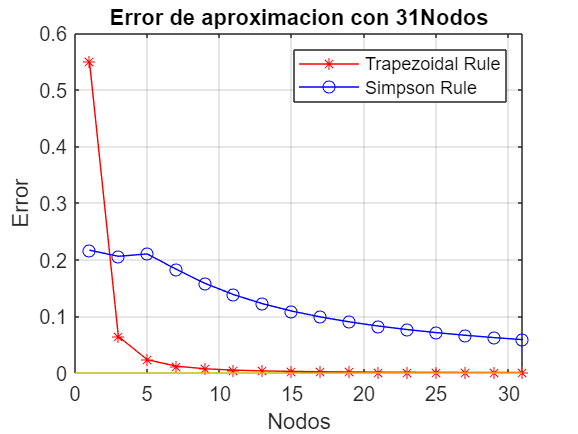


figure(1)
plot(1:2:N,MM(1:2:N,3), '-r*')
hold on
plot(1:2:N, MM(1:2:N,4), '-bo')
yline(0, 'yellow')
title(['Error de aproximacion con ',num2str(N) 'Nodos']);
xlabel('Nodos');
ylabel('Error');
grid on
legend ('Trapezoidal Rule', 'Simpson Rule')
hold off

## Anexo de contenidos

Se aproxima una integral mediante una **cuadratura** numérica, que por definición son como aparece en $\left(p\right)$, están compuestas por puntos y pesos de casa ese punto, incluyendo un error que hace que LHS no sea igual a RHS. 

El planteamiento de una cuadratura numérica incluye

- Aproximar f por un polinomio con interpolación de Lagrange

- Integrar

Según como sean los puntos de integración tendremos métodos como Newton-Cotes (puntos arbitrarios con datos experimentales) y Gauss (puntos óptimos). En el primer caso que es de nuestro interés podemos notar que 

- Generalmente los puntos son equiespaciados

- Solo hay que determinar los pesos ${{\left\lbrace w_i \right\rbrace }_0 }^n$ y el error $E_n$

Según como sean sus extremos tendremos cuadraturas cerradas y cuadraturas abiertas.

Según el orden de una cuadratura, diremos que si la cuadratura se obtiene integrando el polinomio interpolador $p_n \left(x\right)$, entonces la cuadratura es de orden n o superior. 

#### Formulas cerradas de Newton-Cotes

- Puntos ${{\left\lbrace x_i \right\rbrace }_0 }^n$ arbitrarios

- Solo hay que calcular los pesos $\left(w_i \right)$ y el error $E_n$

 $w_{i\;} =\int_a^b L_i \left(x\right)\textrm{dx}$       (A.1)

 $E_{n\;} =\int_a^b R_n \left(x\right)\textrm{dx}$      (A.2)

- Cuadraturas tabuladas para *puntos equiespaciados*

$x_i =x_o +\textrm{ih}=a+\textrm{ih}$    (A.3)

Donde, 

$h=\textrm{step}\;\textrm{size}=\frac{\textrm{end}\;\textrm{limit}-\textrm{start}\;\textrm{limit}}{\textrm{Number}\;\textrm{of}\;\textrm{trapeziums}}=\frac{b-a}{n}$              (A.4)

**Numero de puntos de datos = Numero de trapezios + 1**

Podemos hacer un cambio de variable para poder hacer la sumatoria 

$x=x_o +\alpha \;h$ (A.5)

Donde los puntos de integración $x_{i\;} =x_o +\textrm{ih}$ corresponden a $\alpha =0,1\;,2,\ldotp \ldotp \ldotp ,n$

**Regla del trapezoide**


$$\int_a^b f\left(x\right)\textrm{dx}\approx \frac{h}{2}\;\left\lbrack f\left(a\right)+2\left\lbrace f\left(x_1 \right)+f\left(x_2 \right)+f\left(x_3 \right)+\ldotp \ldotp \ldotp +f\left(x_{N-1} \right)\right\rbrace +f\left(b\right)\right\rbrack$$


**Regla de Simpson 1 a 3era **


$$\int_a^b f\left(x\right)\textrm{dx}\approx \frac{h}{3}\;\left\lbrack f\left(a\right)+4\left\lbrace f\left(x_1 \right)+f\left(x_3 \right)+\;f\left(x_5 \right)\;+\;f\left(x_7 \right)+\ldotp \ldotp \ldotp +f\left(x_{N-1} \right)\right\rbrace +2\left\lbrace f\left(x_2 \right)+f\left(x_4 \right)+f\left(x_6 \right)+\ldotp \ldotp \ldotp +f\left(x_{N-2} \right)\right\rbrace +f\left(b\right)\right\rbrack$$


## Referencias

Burden, R. L., & Faires, J. D. (2011). Numerical analysis (9th ed.). Boston, MA: Brooks/Cole, Cengage Learning.